Trato de hacer una realimentación para ubicar los polos en ciertos lugares específicos:

Cargo los datos

A=[-2,0;0,5]

A =     -2     0
     0     5


B=[1;2]

B =      1
     2


C=[1, 5]

C =      1     5


D=0

D = 0


ss_system = ss(A,B,C,D)


ss_system =
 
  A = 
       x1  x2
   x1  -2   0
   x2   0   5
 
  B = 
       u1
   x1   1
   x2   2
 
  C = 
       x1  x2
   y1   1   5
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.
Model Properti

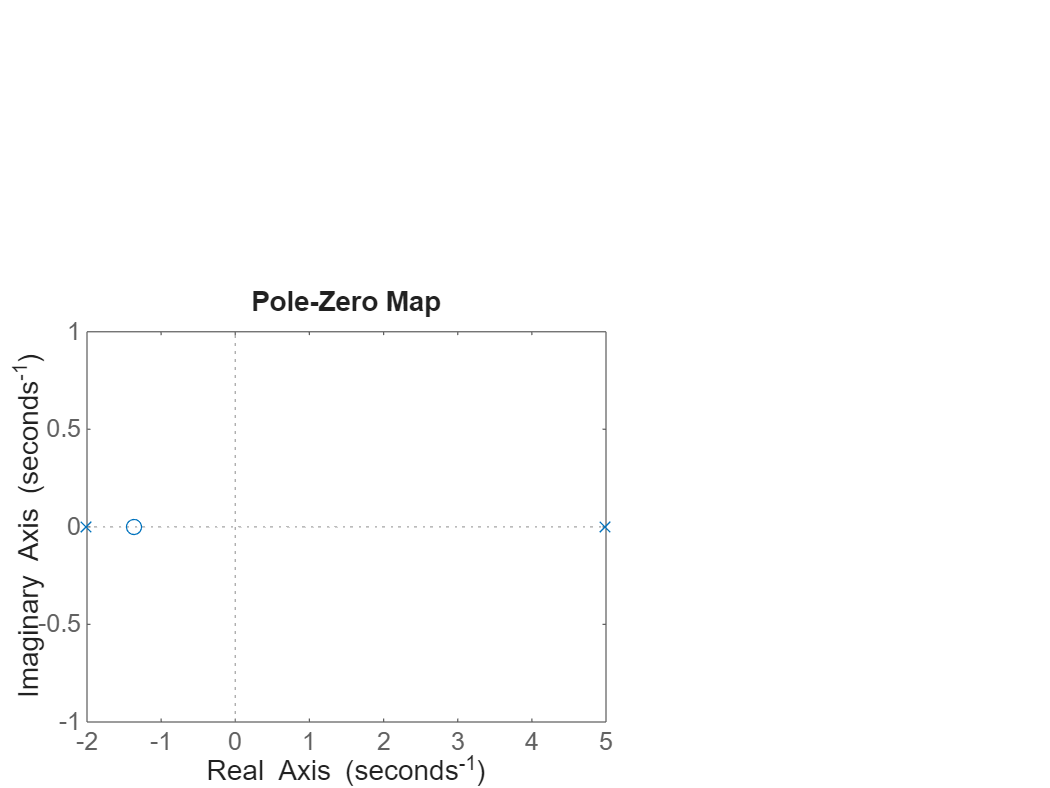


pzmap(ss_system)

[p, z] = pzmap(ss_system)

p =     -2
     5


z = -1.3636

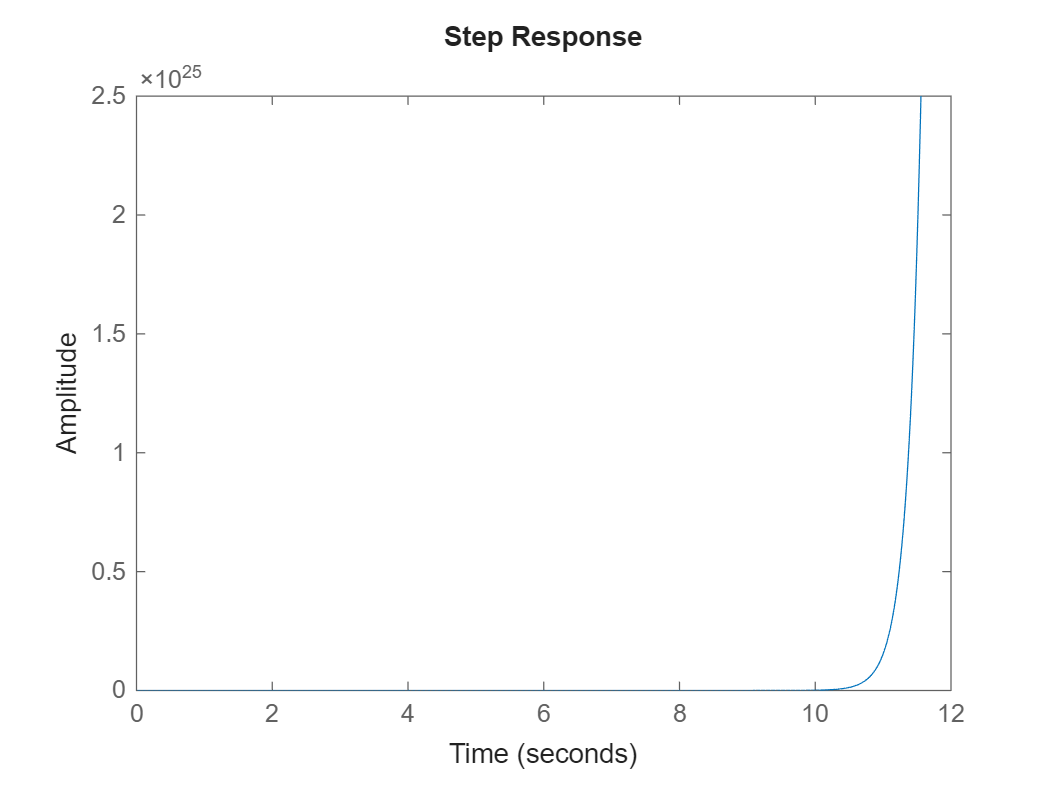


step(ss_system)

Realimento con las ganancias calculadas para que tenga dos polos, uno en -100 y otro en -10. Osea que el polo dominante del sistema sea -10.

K0=-112;
K1=112.5;
K=[K0, K1]

K =  -112.0000  112.5000



reference = 1;

A_LC = A - B*K

A_LC =   110.0000 -112.5000
  224.0000 -220.0000


B_LC = B*reference

B_LC =      1
     2



ss_system_cl = ss(A_LC, B_LC, C, D)


ss_system_cl =
 
  A = 
           x1      x2
   x1     110  -112.5
   x2     224    -220
 
  B = 
       u1
   x1   1
   x2   2
 
  C = 
       x1  x2
   y1   1   5
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.


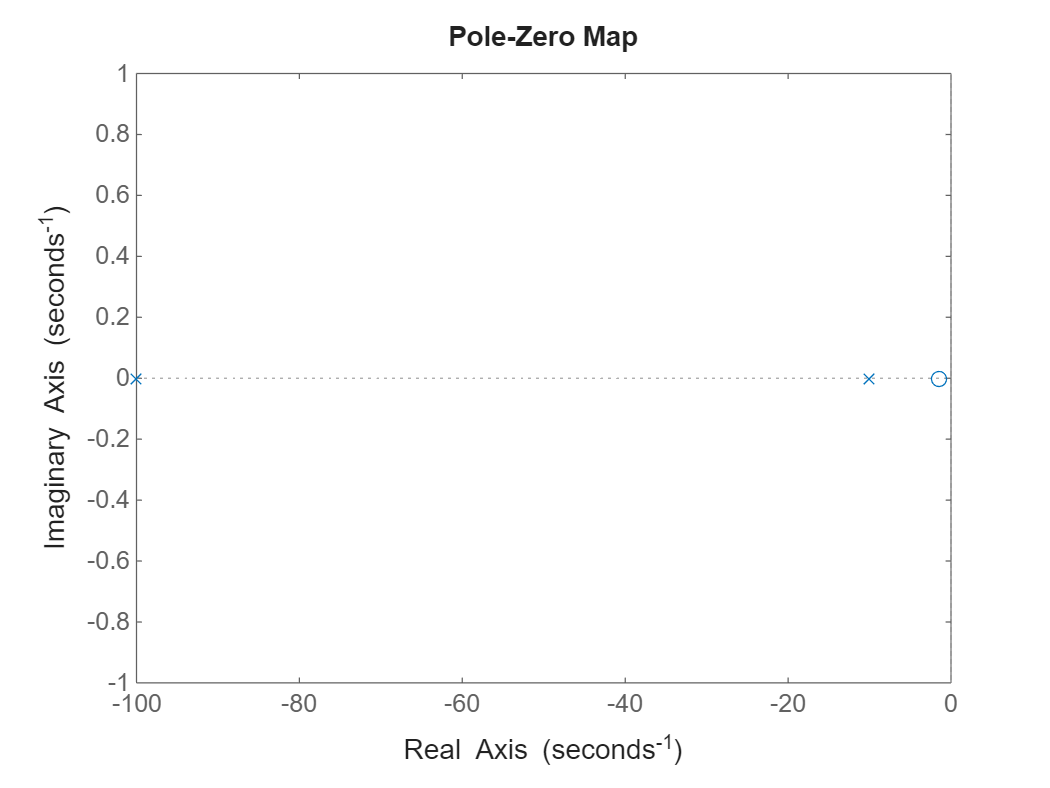


pzmap(ss_system_cl)

[p, z] = pzmap(ss_system_cl)

p =   -10.0000
 -100.0000


z = -1.3636

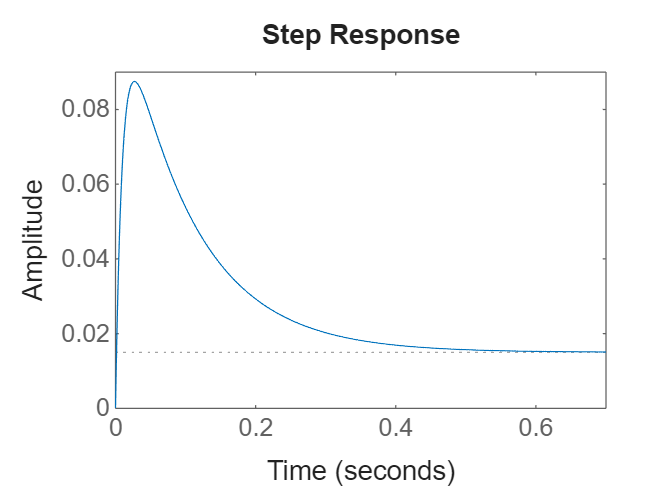


step(ss_system_cl)

Ahora diseño un sistema expandido para que tenga un polo en el origen, osea se añade un integrador al error

A_e = [A, zeros(length(A), 1); -C, 0]

A_e =     -2     0     0
     0     5     0
    -1    -5     0


B_e = [B, zeros(length(A), 1); 0, 1]

B_e =      1     0
     2     0
     0     1


C_e = [C, 0]

C_e =      1     5     0


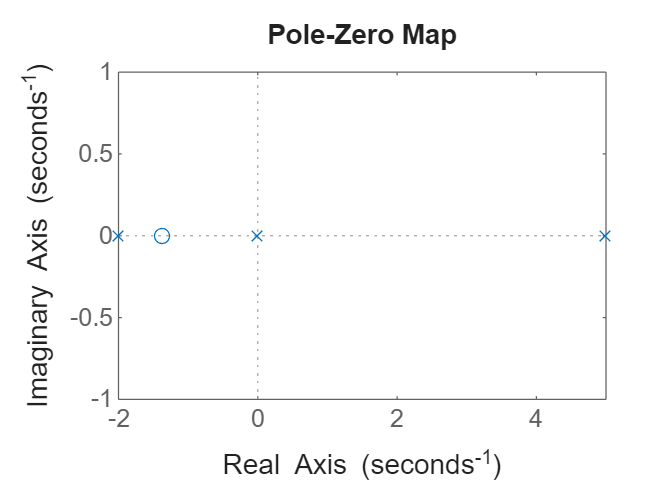


ss_system_cl_int = ss(A_e, B_e, C_e, 0);

pzmap(ss_system_cl_int)

[p, z] = pzmap(ss_system_cl_int)

p =     -2
     5
     0


z = -1.3636